**Grafik **$R_i(x_j)$** pada *****Insecure Individuals***

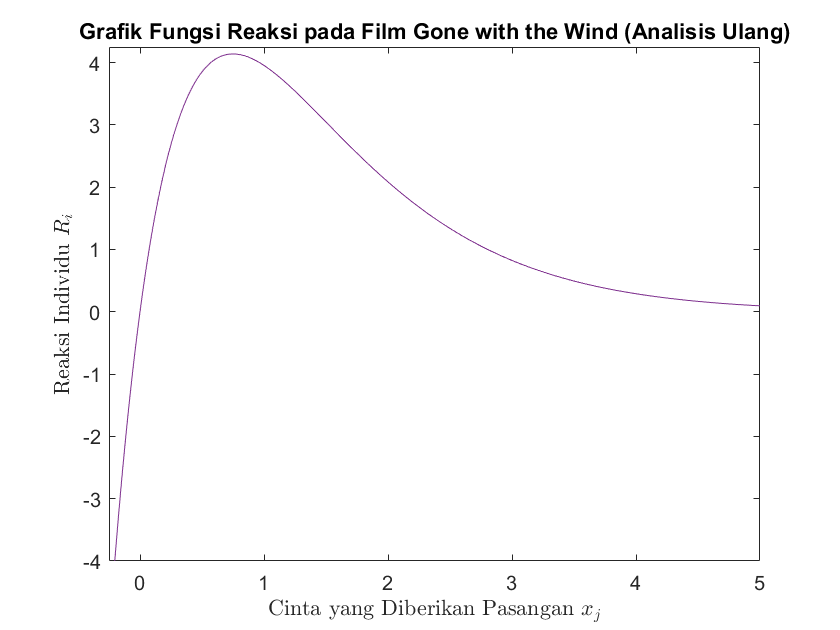

% Nilai Parameter 
ki = 15;
bi = 0.75;

% Fungsi Reaksi i terhadap Cinta j
Ri = @(xj) ki.*xj.*exp(-xj./bi);

% Plot 
xj = -5:0.01:5;
figure 
plot(xj,Ri(xj),"Color","#7E2F8E")
title('Grafik Fungsi Reaksi pada Film Gone with the Wind (Analisis Ulang)')
xlabel('Cinta yang Diberikan Pasangan $x_j$','Interpreter','latex')
ylabel('Reaksi Individu $R_i$','Interpreter','latex')
xlim([-0.25,5])
ylim([-4,4.25])

**Grafik **$R_i(x_j)$** pada *****Secure Individuals***

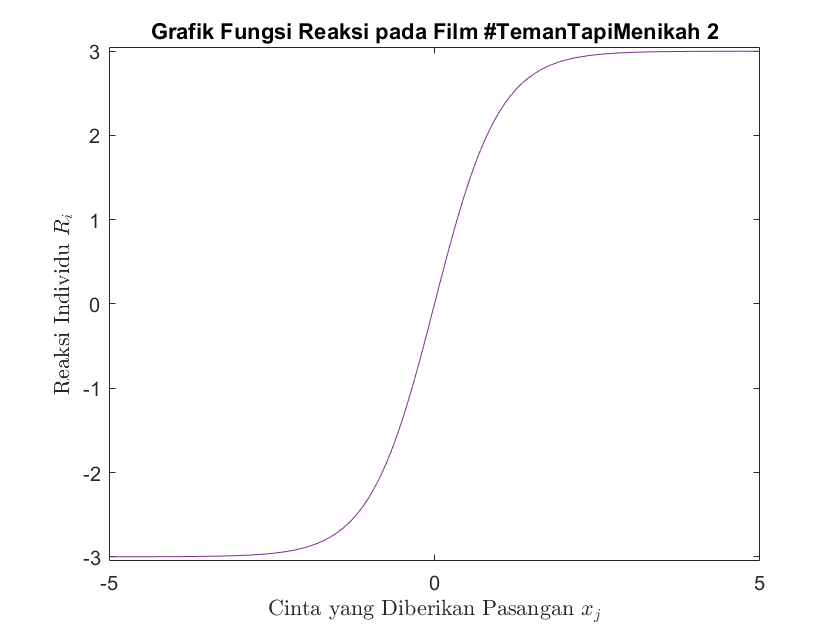

% Nilai Parameter 
% Misalkan R^{+} = max dan R^{-} = min
max = 3;
min = -3;

% Fungsi Reaksi i terhadap Cinta j
Ri = @(xj) (exp(xj)-exp(-xj))./(exp(xj)./max - exp(-xj)./min);

% Plot 
xj = -5:0.01:5;
figure 
plot(xj,Ri(xj),"Color","#7E2F8E")
title('Grafik Fungsi Reaksi pada Film #TemanTapiMenikah 2')
xlabel('Cinta yang Diberikan Pasangan $x_j$','Interpreter','latex')
ylabel('Reaksi Individu $R_i$','Interpreter','latex')
ylim([-3.05,3.05])

**Pemodelan Perasaan Scarlett dan Rhett pada Film *****Gone with the Wind***** (Berdasarkan Referensi)**

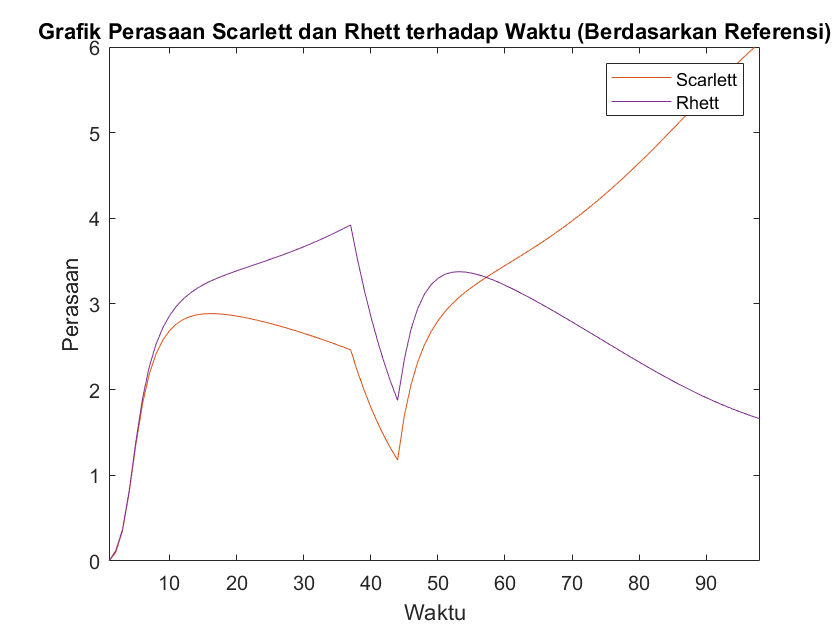

clc; clear all;

% PERASAAN SAAT PERTAMA KALI BERTEMU
x1(1) = 0; 
x2(1) = 0;  

% FIXED PARAMETERS
dt = 0.1;
alpha1 = 1;
alpha2 = 1;
rho1 = 1;
rho2 = 1;
k1 = 15;
k2 = 15;
beta1 = 1;
beta2 = 1; 
R1 = @(x2) k1*x2*exp(-x2/beta1);
R2 = @(x1) k2*x1*exp(-x1/beta2);

% FASE 1
% Scarlett lebih menarik secara fisik daripada Rhett. 
% Kekayaan dianggap tidak mempengaruhi ketertarikan satu sama lain.
% Jadi, A1 > A2
% Nilai Parameter
A1 = 1.2;
A2 = 1;
for t = 1:36
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end


% FASE 2
% Perpisahan karena perang. 
% Hanya proses peluruhan ingatan dan perasaan yang aktif.
for t = 37:43
    x1(t+1) = -alpha1*x1(t)*dt + x1(t);
    x2(t+1) = -alpha2*x2(t)*dt + x2(t);
end

% FASE 3
% Scarlett bangkrut dan butuh pasokan uang dari Rhett.
% Jadi, A1 < A2
% Nilai Parameter
A1 = 1.2;
A2 = 2;
for t = 44:97
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% PLOT PERASAAN TERHADAP WAKTU
t = [1:98];
plot(t,x1,"Color","#D95319")
hold on
plot(t,x2,"Color","#7E2F8E")
legend('Scarlett','Rhett')
title('Grafik Perasaan Scarlett dan Rhett terhadap Waktu (Berdasarkan Referensi)')
xlabel('Waktu')
ylabel('Perasaan')
xlim([1,98])
ylim([0,6])
hold off

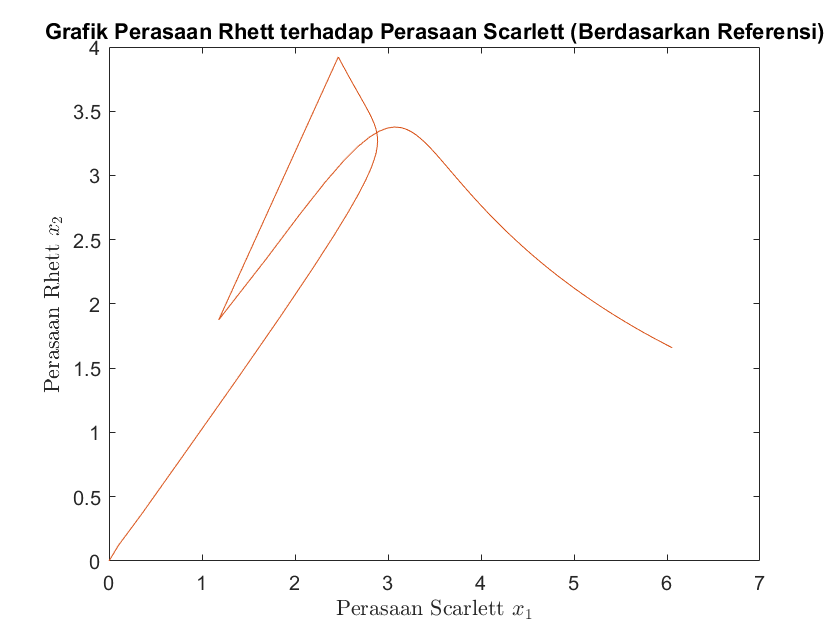

% PLOT PERASAAN RHETT TERHADAP PERASAAN SCARLETT
plot(x1,x2,"Color","#D95319")
title('Grafik Perasaan Rhett terhadap Perasaan Scarlett (Berdasarkan Referensi)')
xlabel('Perasaan Scarlett $x_1$','interpreter','latex')
ylabel('Perasaan Rhett $x_2$','interpreter','latex')

**Pemodelan Perasaan Scarlett dan Rhett pada Film *****Gone with the Wind***** (Analisis Ulang)**

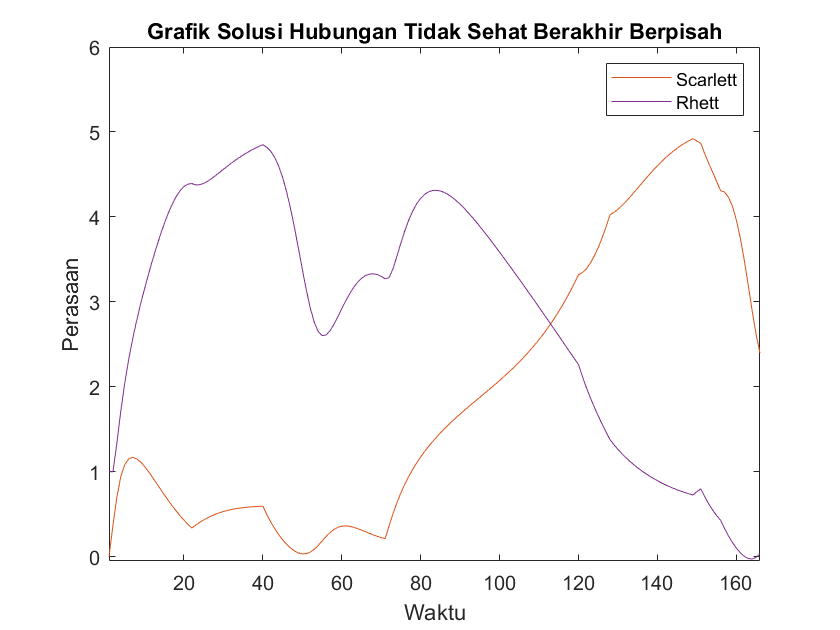

clc; clear all;

% PERASAAN SAAT PERTAMA KALI BERTEMU
% Rhett memandangi Scarlett sambil tersenyum
x1(1) = 0; % Scarlett tidak tertarik  
x2(1) = 1; % Rhett terlihat tertarik 

% FIXED PARAMETERS
dt = 0.1;
rho1 = 1;
rho2 = 1;
k1 = 15;
k2 = 15;
beta1 = 0.75;
beta2 = 0.75; 
R1 = @(x2) k1*x2*exp(-x2/beta1);
R2 = @(x1) k2*x1*exp(-x1/beta2);

% FASE 1
% Nilai Parameter
alpha1 = 1;
alpha2 = 1;
A1 = 1;
A2 = -0.25;
for t = 1:21
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% FASE 2
% Nilai Parameter
alpha1 = 1;
alpha2 = 1;
A1 = 1;
A2 = 0.5;
for t = 22:39
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% FASE 3
% Nilai Parameter
alpha1 = 1;
alpha2 = 1;
A1 = 0.5;
A2 = -0.5;
for t = 40:70
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% FASE 4
% Nilai Parameter
alpha1 = 0.5;
alpha2 = 1;
A1 = 1;
A2 = 1;
for t = 71:119
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% FASE 5
% Nilai Parameter
alpha1 = 0.5;
alpha2 = 1;
A1 = 0.25;
A2 = 0.25;
for t = 120:127
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% FASE 6
% Nilai Parameter
alpha1 = 1;
alpha2 = 1;
A1 = 0.5;
A2 = 1;
for t = 128:148
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% FASE 7
% Nilai Parameter
alpha1 = 1;
alpha2 = 1;
A1 = 1;
A2 = 0.5;
for t = 149:150
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% FASE 8
% Nilai Parameter
alpha1 = 1;
alpha2 = 1;
A1 = -0.25;
A2 = -0.5;
for t = 151:155
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% FASE 9
% Nilai Parameter
alpha1 = 1;
alpha2 = 1;
A1 = -0.75;
A2 = 0.5;
for t = 156:165
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% PLOT PERASAAN TERHADAP WAKTU
t = [1:166];
plot(t,x1,"Color","#D95319")
hold on
plot(t,x2,"Color","#7E2F8E")
legend('Scarlett','Rhett')
title('Grafik Solusi Hubungan Tidak Sehat Berakhir Berpisah')
xlabel('Waktu')
ylabel('Perasaan')
xlim([1,166])
ylim([-0.05,6])
hold off

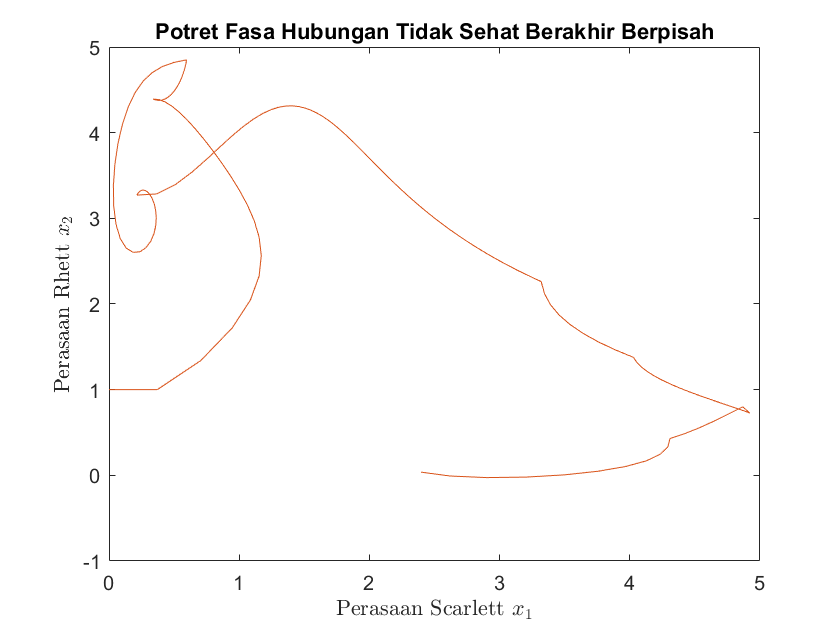

% PLOT PERASAAN RHETT TERHADAP PERASAAN SCARLETT
plot(x1,x2,"Color","#D95319")
title('Potret Fasa Hubungan Tidak Sehat Berakhir Berpisah')
xlabel('Perasaan Scarlett $x_1$','interpreter','latex')
ylabel('Perasaan Rhett $x_2$','interpreter','latex')

**Pemodelan Perasaan Ainun dan Ahmad pada Film *****Habibie & Ainun 3***

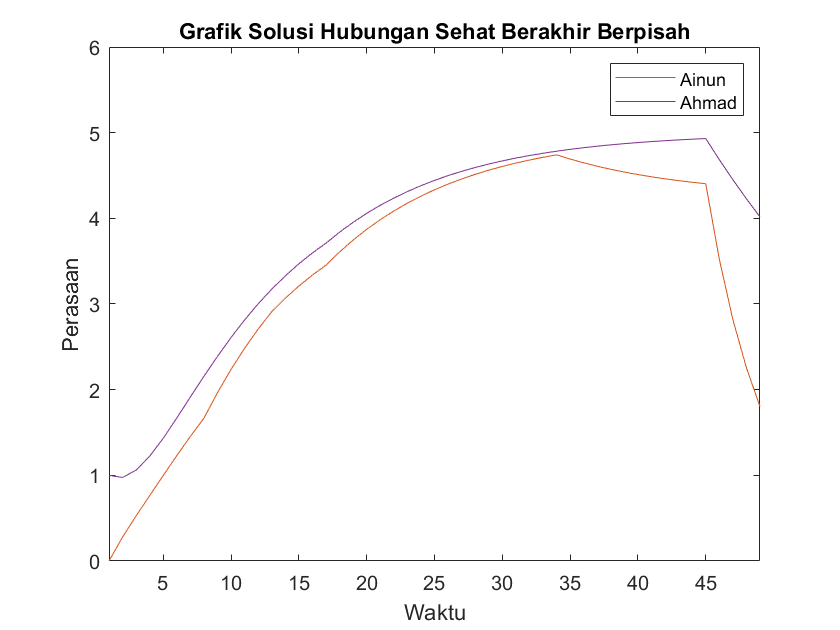

clc; clear all;

% PERASAAN SAAT PERTAMA KALI BERTEMU
x1(1) = 0; % Ainun tidak tertarik  
x2(1) = 1; % Ahmad terlihat tertarik 

% FIXED PARAMETERS
dt = 0.1;
rho1 = 1;
rho2 = 1;
% Misalkan R1+ = R2+ = max dan R1- = R2- = min
max = 4;
min = -4;
R1 = @(x2) (exp(x2)-exp(-x2))./(exp(x2)./max - exp(-x2)./min);
R2 = @(x1) (exp(x1)-exp(-x1))./(exp(x1)./max - exp(-x1)./min);

% FASE 1
% Nilai Parameter
alpha1 = 1;
alpha2 = 1;
A1 = 0.75;
A2 = -0.25;
for t = 1:7
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% FASE 2
% Nilai Parameter
alpha1 = 1;
alpha2 = 1;
A1 = 0.75;
A2 = 0.75;
for t = 8:12
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% FASE 3
% Nilai Parameter
alpha1 = 1;
alpha2 = 1;
A1 = 0.75;
A2 = 0.5;
for t = 13:16
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% FASE 4
% Nilai Parameter
alpha1 = 1;
alpha2 = 1;
A1 = 1;
A2 = 1;
for t = 17:33
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% FASE 5
% Nilai Parameter
alpha1 = 1;
alpha2 = 1;
A1 = 1;
A2 = 0.25;
for t = 34:44
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% FASE 6
% Pasca perpisahan: Dianggap hanya faktor melupakan pasangan yang aktif
% Nilai Parameter
alpha1 = 2; 
alpha2 = 0.5; 
for t = 45:48
    x1(t+1) = (-alpha1*x1(t))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t))*dt + x2(t);
end

% PLOT PERASAAN TERHADAP WAKTU 
t = [1:49];
plot(t,x1,"Color","#D95319")
hold on
plot(t,x2,"Color","#7E2F8E")
legend('Ainun','Ahmad')
title('Grafik Solusi Hubungan Sehat Berakhir Berpisah')
xlabel('Waktu')
ylabel('Perasaan')
xlim([1,49])
ylim([0,6])
hold off

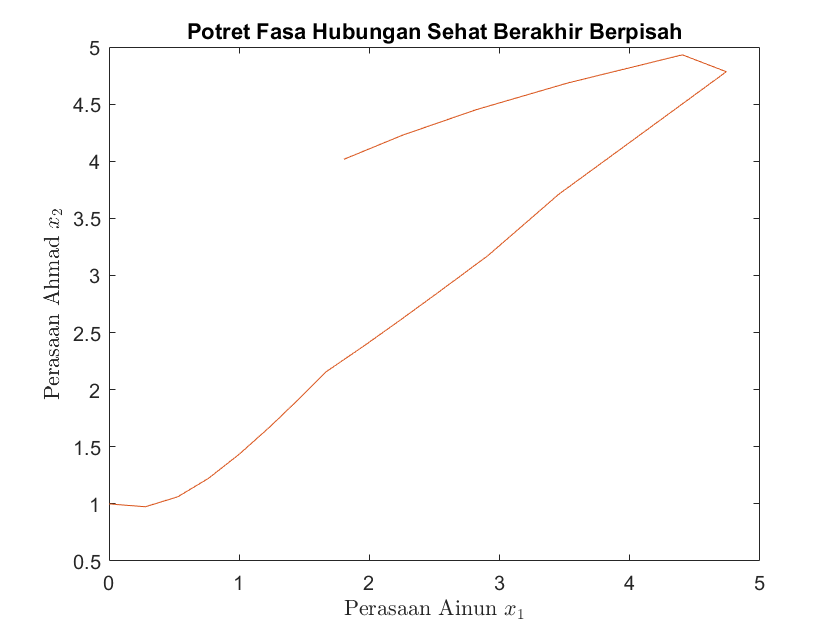

% PLOT PERASAAN AHMAD TERHADAP PERASAAN AINUN
plot(x1,x2,"Color","#D95319")
title('Potret Fasa Hubungan Sehat Berakhir Berpisah')
xlabel('Perasaan Ainun $x_1$','interpreter','latex')
ylabel('Perasaan Ahmad $x_2$','interpreter','latex')

**Pemodelan Perasaan Ayu dan Ditto pada Film *****#TemanTapiMenikah 2***

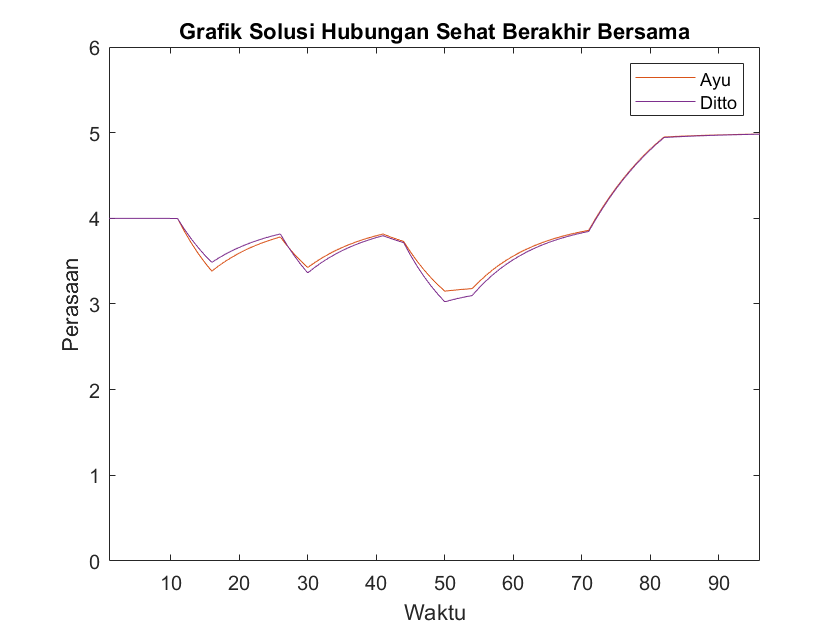

clc; clear all;

% PERASAAN SAAT PERTAMA KALI BERTEMU
x1(1) = 4; % Ayu mencintai Ditto 
x2(1) = 4; % Ditto mencintai Ayu

% FIXED PARAMETERS
dt = 0.1;
rho1 = 1;
rho2 = 1;
% Misalkan R1+ = R2+ = max dan R1- = R2- = min
max = 3;
min = -3;
R1 = @(x2) (exp(x2)-exp(-x2))./(exp(x2)./max - exp(-x2)./min);
R2 = @(x1) (exp(x1)-exp(-x1))./(exp(x1)./max - exp(-x1)./min);

% FASE 1
% Nilai Parameter
alpha1 = 1;
alpha2 = 1;
A1 = 1;
A2 = 1;
for t = 1:10
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% FASE 2
% Nilai Parameter
alpha1 = 1;
alpha2 = 1;
A1 = -0.25;
A2 = -0.5;
for t = 11:15
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% FASE 3
% Nilai Parameter
alpha1 = 1;
alpha2 = 1;
A1 = 1;
A2 = 1;
for t = 16:25
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% FASE 4
% Nilai Parameter
alpha1 = 1;
alpha2 = 1;
A1 = -0.5;
A2 = -0.25;
for t = 26:29
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% FASE 5
% Nilai Parameter
alpha1 = 1;
alpha2 = 1;
A1 = 1;
A2 = 1;
for t = 30:40
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% FASE 6
% Nilai Parameter
alpha1 = 1;
alpha2 = 1;
A1 = 0.5;
A2 = 0.5;
for t = 41:43
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% FASE 7
% Nilai Parameter
alpha1 = 1;
alpha2 = 1;
A1 = -0.75;
A2 = -0.5;
for t = 44:49
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% FASE 8
% Nilai Parameter
alpha1 = 1;
alpha2 = 1;
A1 = 0.25;
A2 = 0.25;
for t = 50:53
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% FASE 9
% Nilai Parameter
alpha1 = 1;
alpha2 = 1;
A1 = 1;
A2 = 1;
for t = 54:70
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% FASE 10
% Nilai Parameter
alpha1 = 0.68;
alpha2 = 0.68;
A1 = 1;
A2 = 1;
for t = 71:81
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% FASE 11
% Nilai Parameter
alpha1 = 0.8;
alpha2 = 0.8;
A1 = 1;
A2 = 1;
for t = 82:95
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% PLOT PERASAAN TERHADAP WAKTU
t = [1:96];
plot(t,x1,"Color","#D95319")
hold on
plot(t,x2,"Color","#7E2F8E")
legend('Ayu','Ditto')
title('Grafik Solusi Hubungan Sehat Berakhir Bersama')
xlabel('Waktu')
ylabel('Perasaan')
xlim([1,96])
ylim([0,6])
hold off

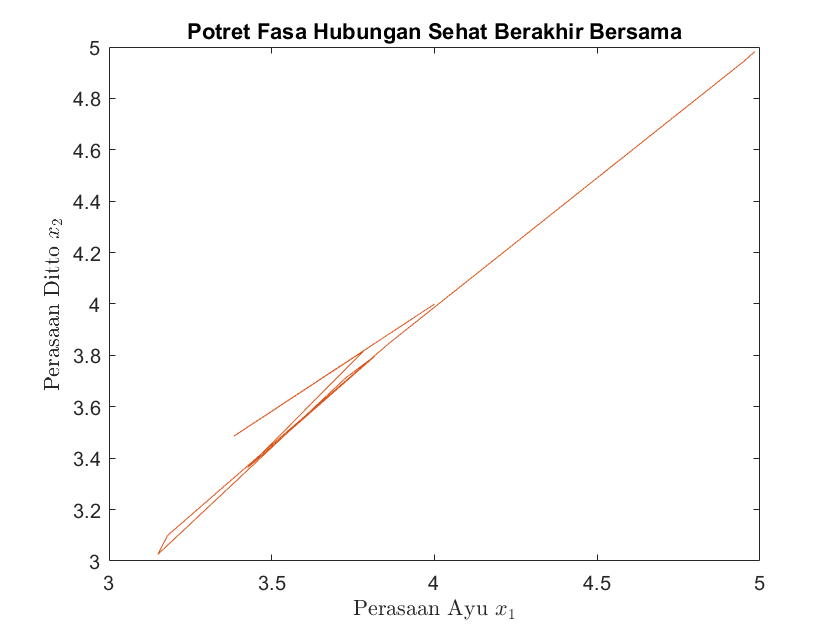


% PLOT PERASAAN DITTO TERHADAP PERASAAN AYU
plot(x1,x2,"Color","#D95319")
title('Potret Fasa Hubungan Sehat Berakhir Bersama')
xlabel('Perasaan Ayu $x_1$','interpreter','latex')
ylabel('Perasaan Ditto $x_2$','interpreter','latex')

**Pemodelan Perasaan Ambar dan Gilang pada Film *****Noktah Merah Perkawinan***

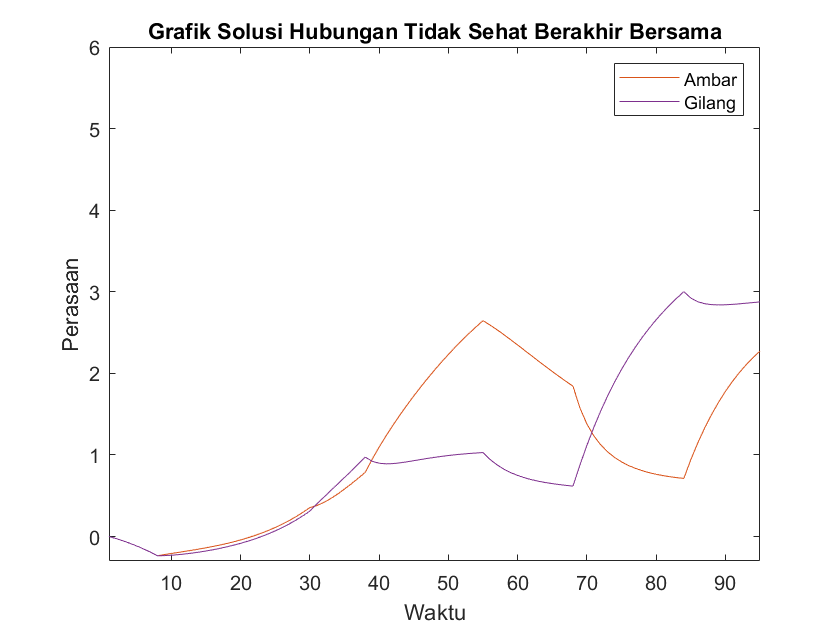

clc; clear all;

% PERASAAN SAAT PERTAMA KALI BERINTERAKSI
x1(1) = 0; % Ambar menunjukkan sikap dingin 
x2(1) = 0; % Gilang menunjukkan sikap dingin

% FIXED PARAMETERS
dt = 0.1;
rho1 = 1;
rho2 = 1;
% Misalkan R1+ = R2+ = max dan R1- = R2- = min
max = 2;
min = -2;
R1 = @(x2) (exp(x2)-exp(-x2))./(exp(x2)./max - exp(-x2)./min);
R2 = @(x1) (exp(x1)-exp(-x1))./(exp(x1)./max - exp(-x1)./min);

% FASE 1
% Nilai Parameter
alpha1 = 1;
alpha2 = 1;
A1 = -0.25;
A2 = -0.25;
for t = 1:7
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% FASE 2
% Nilai Parameter
alpha1 = 1;
alpha2 = 1;
A1 = 0.25;
A2 = 0.375;
for t = 8:29
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% FASE 3
% Nilai Parameter
alpha1 = 1;
alpha2 = 1;
A1 = 0.5;
A2 = 0;
for t = 30:37
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% FASE 4
% Nilai Parameter
alpha1 = 0.5;
alpha2 = 2;
A1 = 0.125;
A2 = 0.5;
for t = 38:54
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% FASE 5
% Nilai Parameter
alpha1 = 0.5;
alpha2 = 2;
A1 = -0.75;
A2 = -0.75;
for t = 55:67
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% FASE 6
% Nilai Parameter
alpha1 = 1.5;
alpha2 = 0.5;
A1 = 1;
A2 = -1;
for t = 68:83
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% FASE 7
% Nilai Parameter
alpha1 = 1;
alpha2 = 1;
A1 = 1;
A2 = 1;
for t = 84:94
    x1(t+1) = (-alpha1*x1(t) + rho1*A2 + R1(x2(t)))*dt + x1(t);
    x2(t+1) = (-alpha2*x2(t) + rho2*A1 + R2(x1(t)))*dt + x2(t);
end

% PLOT PERASAAN TERHADAP WAKTU
t = [1:95];
plot(t,x1,"Color","#D95319")
hold on
plot(t,x2,"Color","#7E2F8E")
legend('Ambar','Gilang')
title('Grafik Solusi Hubungan Tidak Sehat Berakhir Bersama')
xlabel('Waktu')
ylabel('Perasaan')
xlim([1,95])
ylim([-0.3,6])
hold off

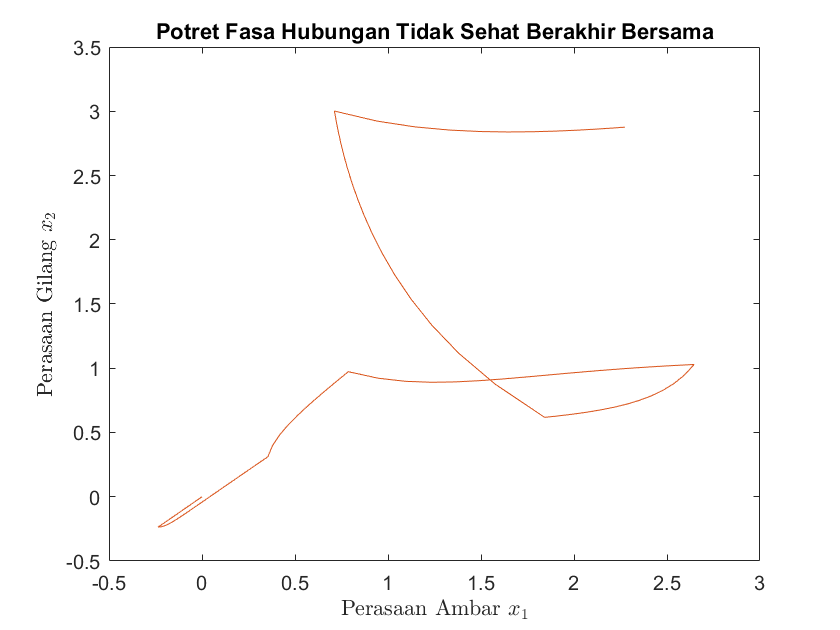


% PLOT PERASAAN GILANG TERHADAP PERASAAN AMBAR
plot(x1,x2,"Color","#D95319")
title('Potret Fasa Hubungan Tidak Sehat Berakhir Bersama')
xlabel('Perasaan Ambar $x_1$','interpreter','latex')
ylabel('Perasaan Gilang $x_2$','interpreter','latex')